# Upstream Balanced Valve

clear
close all

## Definitions

### Plunger

pl_d_out   =	6;	% mm
pl_d_hole  =	1;    % mm
pl_height  =	15.5;	    % mm
pl_d_in    =	6;	% mm
pl_A_out   =    pl_d_out^2/4*pi;    % mm^2
pl_A_hole  =    pl_d_hole^2/4*pi    % mm^2

pl_A_hole = 0.7854

pl_A_in    =    pl_d_in^2/4*pi;    % mm^2
pl_A_u     =    pl_A_out - pl_A_in;     % mm^2
pl_m       =    0.012;  % kg
pl_rom     =    0.0059;  % m

## Design Params

load('design_params.mat');
load('ubv_electromagnetic.mat');

### Volume

vol_top_section = 4416*1e-9; %m3
vol_mid_section = 3977*1e-9; %m3
vol_spring_section = 11699*1e-9; %m3

## Init arrays

%dt = 0.000001; % s
%T = 0.02/dt; % s
% t = zeros(T); % s
% P_ac = zeros(T); % bar
% T_ac = zeros(T); % K
% P_u = zeros(T); % bar
% T_u = zeros(T); % K
% P_d = zeros(T); % bar
% T_d = zeros(T); % K
% P_ups = zeros(T); % K
% T_ups = zeros(T); % K
% P_dps = zeros(T); % K
% T_dps = zeros(T); % K
% 
% x = zeros(T); % m
% v = zeros(T); % m/s
% a = zeros(T); % m/s^2
% 
% V_ac = zeros(T); % mm^3
% 
% pilot = zeros(T); % 1 = open, 0 = closed
% 
% A_m = zeros(T); % mm^2
% 
% m_dot_u_ups = zeros(T); % kg/s
% m_dot_ups_ac = zeros(T); % kg/s
% m_dot_ac_dps = zeros(T); % kg/s
% m_dot_ups_dps = zeros(T); % kg/s
% m_dot_dps_d = zeros(T); % kg/s
% 
% m_dot_ac_net = zeros(T); % kg/s
% m_dot_ups_net = zeros(T); % kg/s
% m_dot_dps_net = zeros(T); % kg/s
% 
% F_ac = zeros(T); % N
% F_d = zeros(T); % N
% F_u = zeros(T); % N
% F_f = zeros(T); % N
% F_s = zeros(T); % N
% F = zeros(T); % N
% 
% m_ac = zeros(T);
% m_ups = zeros(T);
% m_dps = zeros(T);

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 400 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 400 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

dt = 1e-8; % s
T = 0.05/dt; % s
gam = 1.4;
R = 296.8; % kJ/kgK
polythropic_index = 1.1 ;

damper = 0; % kg/s
valve_max_area = 50; %mm2
valve_area(1) = 0; %mm2

t(1) = 0; % s
P_U = 70; % Bar
T_U = 273; % K
P_D = 1; % Bar
T_D = 273; % K
P_ups(1) = P_U; % bar
T_ups(1) = T_U; % K
P_mid(1) = P_ups(1); % bar
T_mid(1) = T_ups(1); % K
P_top(1) = P_D; % bar
T_top(1) = T_D; % K
P_spring(1) = P_D; % bar
T_spring(1) = T_D; % K
P_dps(1) = P_D; % K
T_dps(1) = T_D; % K

x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2

pilot(1) = 0; % 1 = open, 0 = closed

A_o_top(1) = x(1)/dynamic.valve.rom;
A_o_bot(1) = x(1)/dynamic.valve.rom;

m_dot_u_ups(1) = 0; % kg/s
m_dot_ups_mid(1) = 0; % kg/s
m_dot_mid_top(1) = 0; % kg/s
m_dot_mid_spring(1) = 0; % kg/s
m_dot_spring_top(1) = 0; % kg/s
m_dot_top_dps(1) = 0; % kg/s
m_dot_dps_d(1) = 0; % kg/s

m_dot_mid_net(1) = 0; % kg/s
m_dot_top_net(1) = 0; % kg/s
m_dot_spring_net(1) = 0; % kg/s

K = 5 * 1e3 % N/mm

K = 5000

F_p(1) = B_to_Pa(P_spring(1) - P_top(1)) * (0.25 * pi*dynamic.valve.mid_casing_orifice^2) * 10^-6; % N
F_s(1) = - K * (4*1e-3 + x(1)); % N
F_f(1) = - damper * v(1); % N
F(1) = F_f(1) + F_f(1) + F_s(1) + F_p(1); % N

m_ups(1) = 0.014 * B_to_Pa(P_ups(1)) * V_ups / (T_ups(1) * R);
m_mid(1) = 0.014 * B_to_Pa(P_mid(1)) * vol_mid_section / (T_mid(1) * R);
m_spring(1) = 0.014 * B_to_Pa(P_spring(1)) * vol_spring_section / (T_spring(1) * R);
m_top(1) = 0.014 * B_to_Pa(P_top(1)) * vol_top_section / (T_top(1) * R);
m_dps(1) = 0.014 * B_to_Pa(P_dps(1)) * V_dps / (T_dps(1) * R);

EqP_ups(1) = P_U;
EqT_ups(1) = T_U;
EqP_dps(1) = P_U;
EqT_dps(1) = T_D;
Eqm_dot_u_ups(1) = 0; % kg/s
Eqm_dot_ups_dps(1) = 0; % kg/s
Eqm_dot_dps_d(1) = 0; % kg/s
Eqx(1) = 0; % m
Eqv(1) = 0; % m/s
Eqa(1) = 0; % m/s^2
Eqm_ups(1) = 0.014 * B_to_Pa(EqP_ups(1)) * V_ups / (EqT_ups(1) * R);
Eqm_dps(1) = 0.014 * B_to_Pa(EqP_dps(1)) * V_dps / (EqT_dps(1) * R);
Eqvalve_area(1) = 0; %mm2
Eqvalve_pressure_surface = valve_max_area %(valve_max_area/(pi * dynamic.valve.rom * 2))^2 * pi

Eqvalve_pressure_surface = 50


EqF_p(1) = B_to_Pa(EqP_ups(1) - EqP_dps(1)) * Eqvalve_pressure_surface * 10^-6; % N
EqF_s(1) = - K * (4*1e-3 + Eqx(1)); % N
EqF_f(1) = - damper * Eqv(1); % N
EqF(1) = EqF_f(1) + EqF_s(1) - EqF_p(1); % N

V(1) = dynamic.V;
I(1) = 0;
[Fmag(1),N,wire_len,wire_R,sol_V(1),sol_P(1),L(1),reluctance(1)] = valve_magnetic_force(dynamic.valve,dynamic.valve.rom,I(1),0);
t(1) = 0;
di_dt(1) = V(1) / L(1);
total_energy(1) = 0;

old_V(1) = dynamic.V;
old_I(1) = 0;
old_di_dt(1) = 0;

f = waitbar(0, 'Starting');

for i = 2:(T-1)
    if mod(i,round(T/100)) == 0
        waitbar(i/T, f, sprintf('Progress: %d %%', floor(i/T*100)));
    end

    t(i) = t(i-1) + dt; % s

    signal(i) = i < (0.5*T); % 1 = open, 0 = closed

    % Old Design Magnetism
    old_I(i) = old_I(i-1) + old_di_dt(i-1) * dt;
    if (signal(i) > 0)
        applied_V = dynamic.V;
    else
        applied_V = 0;
    end
    old_V_L(i) = applied_V - old_I(i) * dynamic.R;
    [Fmag_old(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i),reluctance(i)] =...
        valve_magnetic_force(dynamic.valve,dynamic.valve.rom - x(i-1),old_I(i),0);
    old_di_dt(i) = old_V_L(i) / L(i) ;

    % New Design
    I(i) = I(i-1) + di_dt(i-1) * dt;
    if (signal(i) > 0)
        applied_V = dynamic.V;
        if i < T*0.25
            applied_V = 2 * dynamic.V;
        end
    else
        applied_V = 0;
    end
    V_L(i) = applied_V - I(i) * dynamic.R;
    [Fmag(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i),reluctance(i)] =...
        valve_magnetic_force(dynamic.valve,dynamic.valve.rom - x(i-1),I(i),0);
    di_dt(i) = V_L(i) / L(i) ;
    total_energy(i) = total_energy(i-1) + I(i)^2 * dynamic.R * dt;

    F_p(i) = B_to_Pa(P_spring(i-1) - P_top(i-1)) * (0.25 * pi * dynamic.valve.mid_casing_orifice^2) * 10^-6; % N
    F_s(i) = - K * (4*1e-3 + x(i-1)); % N
    F_f(i) = - damper * v(i-1); % N
    F(i) = Fmag(i) + F_f(i) + F_s(i) + F_p(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / dynamic.valve_spool_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > dynamic.valve.rom * 1e-3
        x(i) = dynamic.valve.rom * 1e-3; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Pilot area with new displacement
    valve_area(i) = x(i)/(dynamic.valve.rom * 1e-3) * valve_max_area; % mm2
    
    % FluidMechanics

    % Upstream Pipe Section related
    m_dot_u_ups(i) = mdot_orifice(P_U,  P_ups(i-1),gam,        io_A*10^-6,T_U,R); % kg/s
    m_dot_ups_mid(i) = mdot_orifice(P_ups(i-1),P_mid(i-1),gam, io_A*10^-6, T_ups(i-1) ,R); % kg/s
    
    [P_ups(i), T_ups(i), m_ups(i)] = tank_discharge_P_io(P_ups(i-1),T_ups(i-1),m_ups(i-1),...
         [T_U,            T_mid(i-1)],...
         [m_dot_u_ups(i), - m_dot_ups_mid(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_ups_net(i) = (m_ups(i) - m_ups(i-1))/dt; % kg/s

    % Mid Section related
    m_dot_mid_top(i) = mdot_orifice(P_mid(i-1),     P_top(i-1),gam,    valve_area(i) *10^-6,T_mid(i-1),R); % kg/s
    m_dot_mid_spring(i) = mdot_orifice(P_mid(i-1),  P_spring(i-1),gam, valve_area(i) *10^-6,T_mid(i-1),R); % kg/s
    
    [P_mid(i), T_mid(i), m_mid(i)] = tank_discharge_P_io(P_mid(i-1),T_mid(i-1),m_mid(i-1),...
         [T_ups(i-1),       T_top(i-1),         T_spring(i-1)],...
         [m_dot_ups_mid(i), - m_dot_mid_top(i), - m_dot_mid_spring(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_mid_net(i) = (m_mid(i) - m_mid(i-1))/dt; % kg/s

    % Spring Section related
    m_dot_spring_top(i) = mdot_orifice(P_spring(i-1),     P_top(i-1),gam, 0.25*pi*3^2*10^-6,T_spring(i-1),R); % kg/s
    
    [P_spring(i), T_spring(i), m_spring(i)] = tank_discharge_P_io(P_spring(i-1),T_spring(i-1),m_spring(i-1),...
         [T_mid(i-1),          T_top(i-1)],...
         [m_dot_mid_spring(i), - m_dot_spring_top(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_spring_net(i) = (m_spring(i) - m_spring(i-1))/dt; % kg/s

    % Top Section related
    m_dot_top_dps(i) = mdot_orifice(P_top(i-1),     P_dps(i-1),gam, oo_A *10^-6,T_top(i-1),R); % kg/s
    
    [P_top(i), T_top(i), m_top(i)] = tank_discharge_P_io(P_top(i-1),T_top(i-1),m_top(i-1),...
         [T_mid(i-1),       T_spring(i-1),       T_dps(i-1)],...
         [m_dot_mid_top(i), m_dot_spring_top(i), -m_dot_top_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_top_net(i) = (m_top(i) - m_top(i-1))/dt; % kg/s

    % Downstream Pipe Section related
    m_dot_dps_d(i) = mdot_orifice(P_dps(i-1),  P_D,gam,oe_o_A    *10^-6,T_dps(i-1),R); % kg/s
    
    [P_dps(i), T_dps(i), m_dps(i)] = tank_discharge_P_io(P_dps(i-1),T_dps(i-1),m_dps(i-1),...
         [T_top(i-1)        T_D],...
         [m_dot_top_dps(i), - m_dot_dps_d(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_dps_net(i) = (m_dps(i) - m_dps(i-1))/dt; % kg/s

    % Equivalent standard Valve
    
    % Calculate forces
    EqF_p(i) = B_to_Pa(EqP_ups(i-1) - EqP_dps(i-1)) * Eqvalve_pressure_surface * 10^-6; % N
    EqF_s(i) = - K * (4*1e-3 + Eqx(i-1)); % N
    EqF_f(i) = - damper * Eqv(i-1); % N
    EqF(i) = Fmag(i) + EqF_f(i) + EqF_s(i) - EqF_p(i); % N
    
    % Calculate displacement from previous forces
    Eqx(i) = Eqx(i-1) + Eqv(i-1)*dt + 0.5*Eqa(i-1)*dt^2; % m
    Eqv(i) = Eqv(i-1) + Eqa(i-1)*dt; % m/s
    Eqa(i) = EqF(i) / pl_m; % m/s^2
    if Eqx(i) < 0
        Eqx(i) = 0; % m
        Eqv(i) = 0; % m/s
        Eqa(i) = 0; % m/s^2
    elseif Eqx(i) > dynamic.valve.rom * 1e-3
        Eqx(i) = dynamic.valve.rom * 1e-3; % m
        Eqv(i) = 0; % m/s
        Eqa(i) = 0; % m/s^2
    end

    Eqvalve_area(i) = Eqx(i)/(dynamic.valve.rom * 1e-3) * valve_max_area; % mm2

    % Upstream Pipe Section related
    Eqm_dot_u_ups(i) = mdot_orifice(P_U,  EqP_ups(i-1),gam,        io_A*10^-6,T_U,R); % kg/s
    Eqm_dot_ups_dps(i) = mdot_orifice(EqP_ups(i-1),EqP_dps(i-1),gam, Eqvalve_area(i)*10^-6, EqT_ups(i-1) ,R); % kg/s
    
    [EqP_ups(i), EqT_ups(i), Eqm_ups(i)] = tank_discharge_P_io(EqP_ups(i-1),EqT_ups(i-1),Eqm_ups(i-1),...
         [T_U,            EqT_dps(i-1)],...
         [Eqm_dot_u_ups(i), - Eqm_dot_ups_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    Eqm_dot_ups_net(i) = (Eqm_ups(i) - Eqm_ups(i-1))/dt; % kg/s

    % Downstream Pipe Section related
    
    Eqm_dot_dps_d(i) = mdot_orifice(EqP_dps(i-1),  P_D,gam, oo_A *10^-6,EqT_dps(i-1),R); % kg/s
    
    [EqP_dps(i), EqT_dps(i), Eqm_dps(i)] = tank_discharge_P_io(EqP_dps(i-1),EqT_dps(i-1),Eqm_dps(i-1),...
         [EqT_ups(i-1),       T_D],...
         [Eqm_dot_ups_dps(i), - Eqm_dot_dps_d(i)] * dt,...
         polythropic_index); % bar, K
    
    Eqm_dot_mid_net(i) = (Eqm_dps(i) - Eqm_dps(i-1))/dt; % kg/s
    
end

try
    tao3index = ceil(3*dynamic.tao/dt);
    t(tao3index)
catch
    tao3index = 1;
end

ans = 0.0168


close(f);

I = I * 1e3;
old_I = old_I * 1e3;
P = I .* V_L * 1e-3;
old_P = old_I .* old_V_L * 1e-3;

## Results

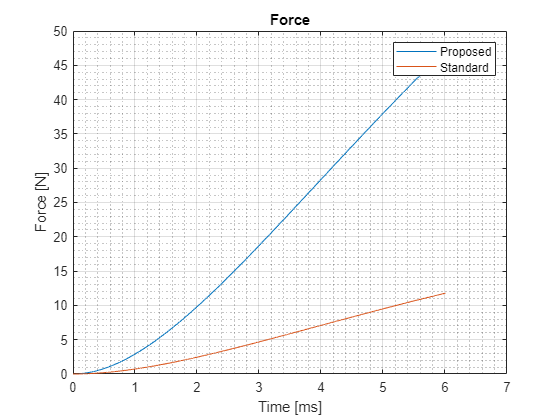

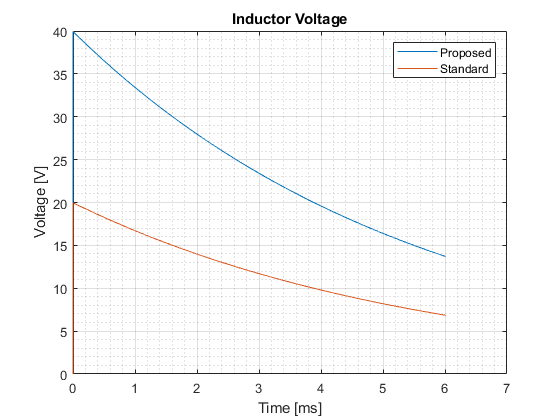

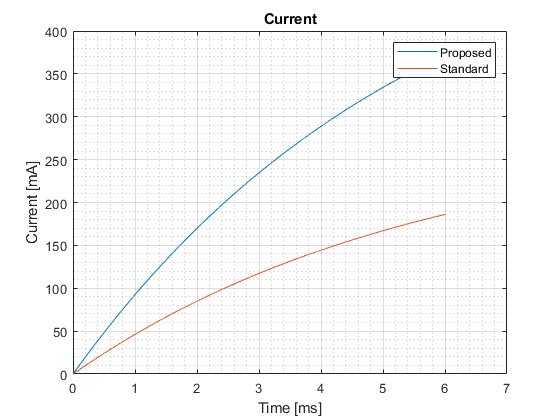

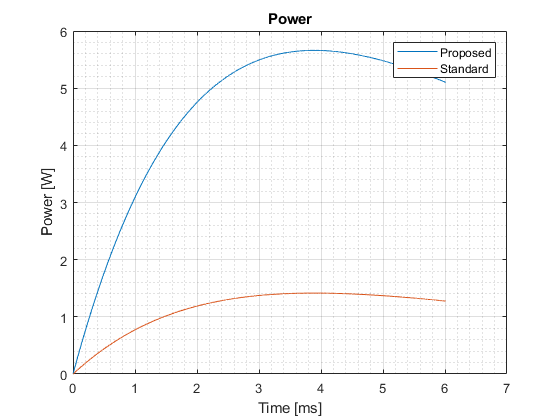

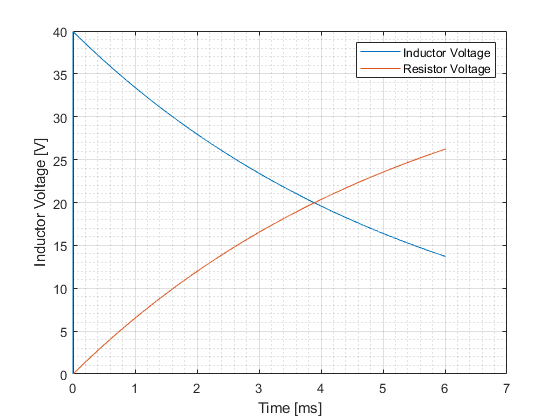

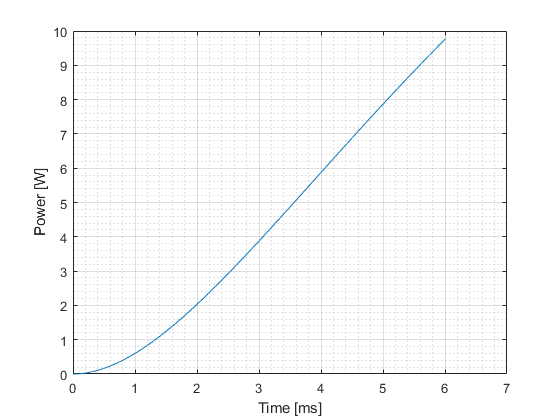

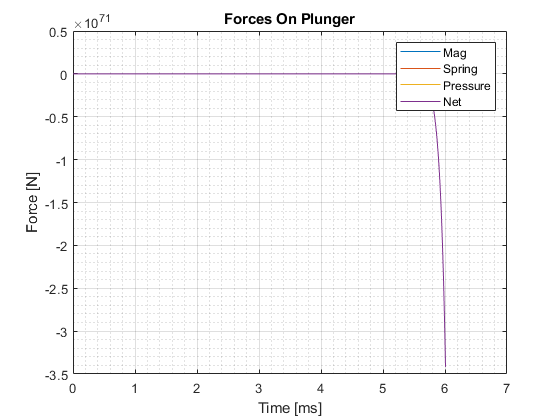

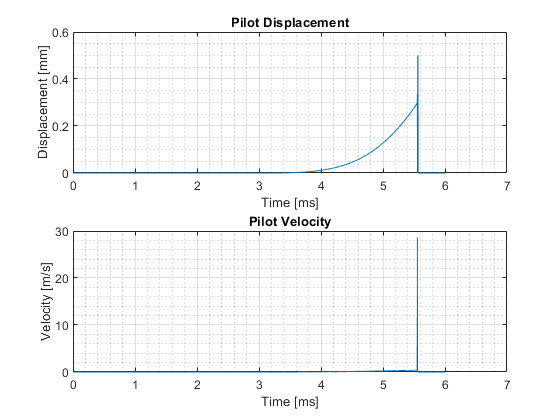

if true
    figure
    plot(t*1e3,Fmag,t*1e3,Fmag_old), legend('Proposed','Standard')
    title('Force'), xlabel('Time [ms]'), ylabel('Force [N]'), grid on, grid minor
    figure
    plot(t*1e3,V_L,t*1e3,old_V_L), legend('Proposed','Standard')
    title('Inductor Voltage'), xlabel('Time [ms]'), ylabel('Voltage [V]'), grid on, grid minor
    figure
    plot(t*1e3,I,t*1e3,old_I), legend('Proposed','Standard')
    title('Current'), xlabel('Time [ms]'), ylabel('Current [mA]'), grid on, grid minor
    figure
    plot(t*1e3,P,t*1e3,old_P), legend('Proposed','Standard')
    title('Power'), xlabel('Time [ms]'), ylabel('Power [W]'), grid on, grid minor
    figure
    plot(t*1e3,V_L,t*1e3,I*1e-3*dynamic.R,t(tao3index)*1e3,V_L(tao3index),'r*')
    legend('Inductor Voltage','Resistor Voltage')
    xlabel('Time [ms]'), ylabel('Inductor Voltage [V]'), grid on, grid minor
    figure
    plot(t*1e3,(I*1e-3).^2*dynamic.R), xlabel('Time [ms]'), ylabel('Power [W]'), grid on, grid minor
    figure
    plot(t*1e3,Fmag,t*1e3,F_s,t*1e3,F_p,t*1e3,F)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Force [N]'), title('Forces On Plunger')
    legend('Mag','Spring','Pressure','Net')
    figure
    subplot(2,1,1)
    plot(t*1e3,x*1e3)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [mm]'), title('Pilot Displacement')
    subplot(2,1,2)
    plot(t*1e3,v)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Velocity [m/s]'), title('Pilot Velocity')
end

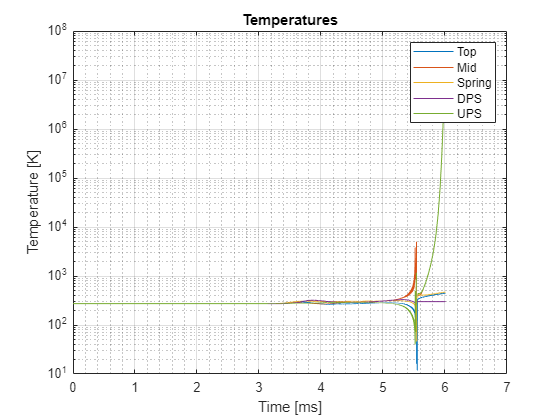

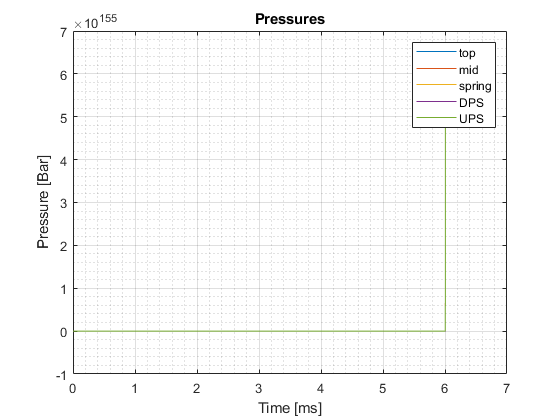

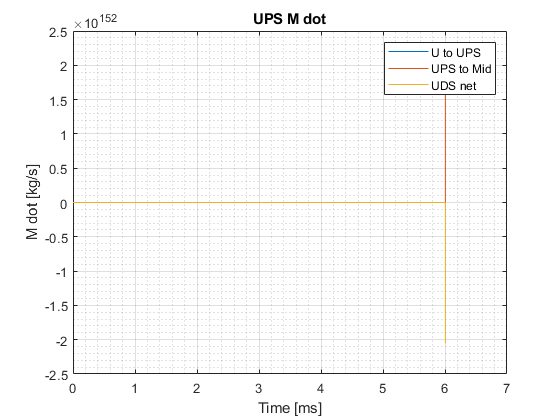

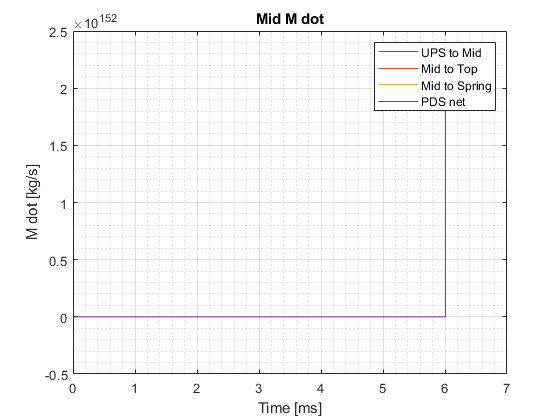

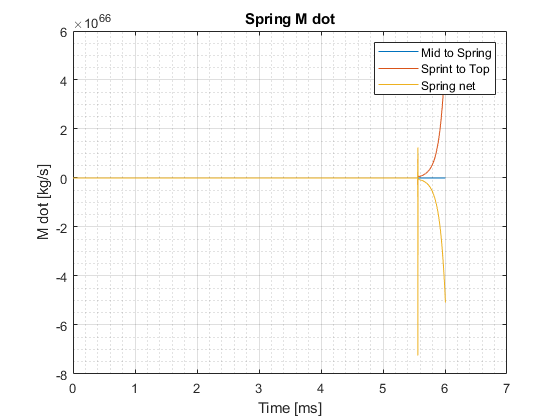

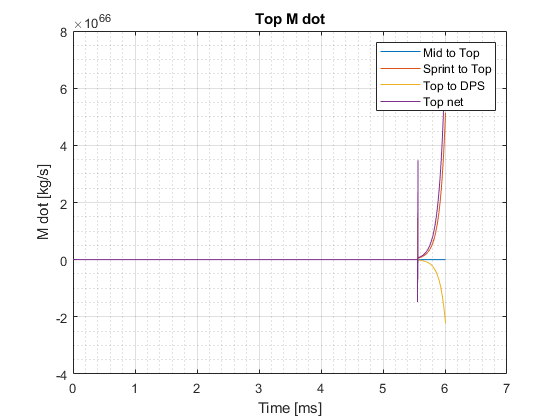

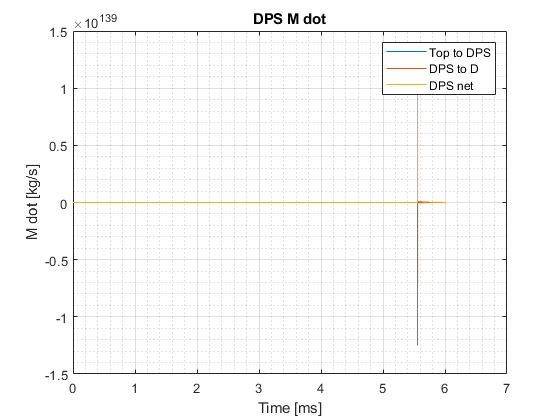

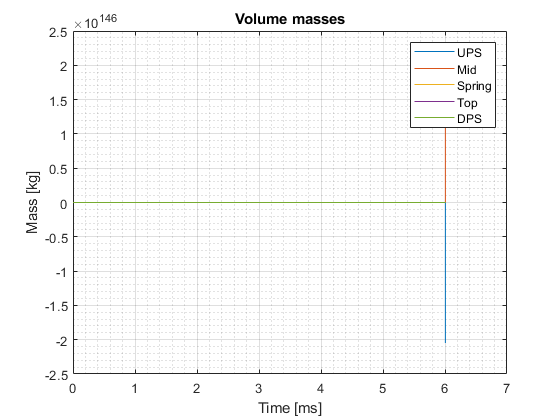

if true
    figure
    semilogy(t*1e3,T_top,t*1e3,T_mid,t*1e3,T_spring,t*1e3,T_dps,t*1e3,T_ups)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Temperature [K]'), title('Temperatures')
    legend('Top','Mid','Spring','DPS','UPS')
    figure
    plot(t*1e3,P_top,t*1e3,P_mid,t*1e3,P_spring,t*1e3,P_dps,t*1e3,P_ups)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('Pressures')
    legend('top','mid','spring','DPS','UPS')
    figure
    plot(t*1e3,m_dot_u_ups,t*1e3,m_dot_ups_mid,t*1e3,m_dot_ups_net)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('M dot [kg/s]'), title('UPS M dot')
    legend('U to UPS', 'UPS to Mid', 'UDS net')
    figure
    plot(t*1e3,m_dot_ups_mid,t*1e3,m_dot_mid_top,t*1e3,m_dot_mid_spring,t*1e3,m_dot_mid_net)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('M dot [kg/s]'), title('Mid M dot')
    legend('UPS to Mid', 'Mid to Top', 'Mid to Spring', 'PDS net')
    figure
    plot(t*1e3,m_dot_mid_spring,t*1e3,m_dot_spring_top,t*1e3,m_dot_spring_net)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('M dot [kg/s]'), title('Spring M dot')
    legend('Mid to Spring', 'Sprint to Top', 'Spring net')
    figure
    plot(t*1e3,m_dot_mid_top,t*1e3,m_dot_spring_top,t*1e3,m_dot_top_dps,t*1e3,m_dot_top_net)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('M dot [kg/s]'), title('Top M dot')
    legend('Mid to Top', 'Sprint to Top', 'Top to DPS', 'Top net')
    figure
    plot(t*1e3,m_dot_top_dps,t*1e3,m_dot_dps_d,t*1e3,m_dot_dps_net)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('M dot [kg/s]'), title('DPS M dot')
    legend('Top to DPS', 'DPS to D', 'DPS net')
    figure
    plot(t*1e3,m_ups,t*1e3,m_mid,t*1e3,m_spring,t*1e3,m_top,t*1e3,m_dps)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Mass [kg]'), title('Volume masses')
    legend('UPS', 'Mid', 'Spring', 'Top', 'DPS')
    figure
    plot(t*1e3,P_dps)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('DPS Pressure')
    figure
    plotyy(t*1e3,m_dot_dps_d,t*1e3,P_dps),legend('m_dot_dps_d','P_dps')
    figure
    plotyy(t*1e3,m_dot_u_ups,t*1e3,P_ups),legend('m_dot_dps_d','P_dps'),title('UPS'),legend('mdot','P')
    figure
    plot(t*1e3,L)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Inductance [H]'), title('Inductance')
    figure
    plot(t*1e3,reluctance)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Reluctance [1/H]'), title('Reluctance')
end

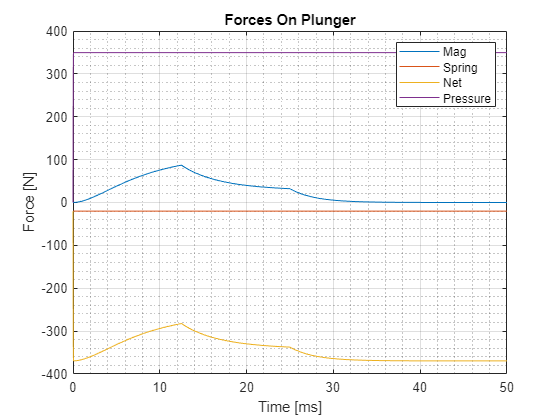

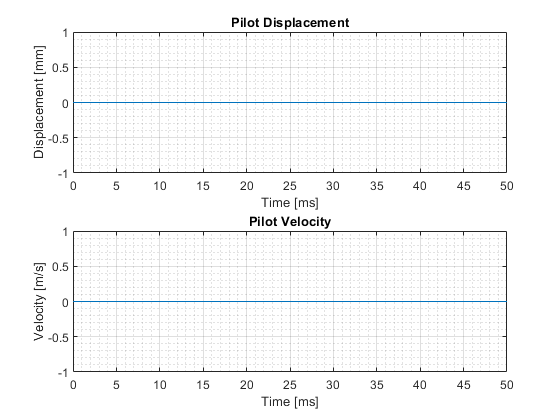

if true
    figure
    plot(t*1e3,Fmag,t*1e3,EqF_s,t*1e3,EqF,t*1e3,EqF_p)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Force [N]'), title('Forces On Plunger')
    legend('Mag','Spring','Net','Pressure')
    figure
    subplot(2,1,1)
    plot(t*1e3,Eqx*1e3)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [mm]'), title('Pilot Displacement')
    subplot(2,1,2)
    plot(t*1e3,Eqv)
    grid on, grid minor, xlabel('Time [ms]'), ylabel('Velocity [m/s]'), title('Pilot Velocity')
end

maxFlowRate  = max(m_dot_dps_d) % kg/s

maxFlowRate = 0.2960

rho = 1.2506

rho = 1.2506

(maxFlowRate / rho) * 3600

ans = 852.1346

plunger_opening_start = t(find(x>0,1))

plunger_opening_start = 0.0031

plunger_opening_end = t(find(x==(dynamic.valve.rom*1e-3),1))

plunger_opening_end = 0.0058

plunger_closing_start = t(find(x==(dynamic.valve.rom*1e-3),1,'last'))

plunger_closing_start = 0.0506

plunger_closing_end = t(find(x==(dynamic.valve.rom*1e-3),1,'last')+...
    find(x(find(x==(dynamic.valve.rom*1e-3),1,'last'):end)==0,1))

plunger_closing_end = 0.0538


opening_time = plunger_opening_end

opening_time = 0.0058

closing_time = plunger_closing_end - dt*T/2

closing_time = 0.0038

save('ubv00_open_close.mat')

## Test Case 2

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 1 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 1 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

%{
dt = 0.000001; % s
T = 0.03/dt; % s
gam = 1.4;
R = 296.8; % kJ/kgK
polythropic_index = gam ;

damper = 1000; % kg/s

t(1) = 0; % s
P_mid(1) = 1; % bar
T_mid(1) = 273; % K
P_top(1) = 400; % bar
T_top(1) = 273; % K
P_spring(1) = 1; % bar
T_spring(1) = 273; % K
P_ups(1) = 1; % K
T_ups(1) = 273; % K
P_dps(1) = 1; % K
T_dps(1) = 273; % K

x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2

V_ac(1) = v_closed; % mm^3

pilot(1) = 0; % 1 = open, 0 = closed

A_m(1) = o_d_in * pi * x(1) * 10^-3; % mm^2

m_dot_u_ups(1) = 0; % kg/s
m_dot_mid_top(1) = 0; % kg/s
m_dot_spring_top(1) = 0; % kg/s
m_dot_top_dps(1) = 0; % kg/s
m_dot_dps_d(1) = 0; % kg/s

m_dot_mid_net(1) = 0; % kg/s
m_dot_top_net(1) = 0; % kg/s
m_dot_spring_net(1) = 0; % kg/s

F_ac(1) = B_to_Pa(P_mid(1)) * pl_A_out * 10^-6; % N
F_d(1) = B_to_Pa(P_dps(1)) * pl_A_in * 10^-6; % N
F_u(1) = B_to_Pa(P_ups(1)) * pl_A_u * 10^-6; % N
F_f(1) = - damper * v(1); % N
F_s(1) = 500; % N
F(1) = - F_ac(1) + F_d(1) + F_u(1) + F_f(1) - F_s(1); % N

m_mid(1) = 0.014 * B_to_Pa(P_mid(1)) * v_closed * 10^-9 / (T_mid(1) * R);
m_top(1) = 0.014 * B_to_Pa(P_ups(1)) * V_ups * 10^-9 / (T_ups(1) * R);
m_spring(1) = 0.014 * B_to_Pa(P_dps(1)) * V_dps * 10^-9 / (T_dps(1) * R);

for i = 2:(T-1)
    t(i) = t(i-1) + dt; % s
    pilot(i) = (i > (0.333*T)) & (i < (0.666*T)); % 1 = open, 0 = closed
    
    P_top(i) = P_top(i-1); % bar
    T_top(i) = T_top(i-1); % K
    P_spring(i) = P_spring(i-1); % bar
    T_spring(i) = T_spring(i-1); % K
    
    % Calculate forces
    F_ac(i) = B_to_Pa(P_mid(i-1)) * pl_A_out * 10^-6; % N
    F_d(i) = B_to_Pa(P_dps(i-1)) * pl_A_in * 10^-6; % N
    F_u(i) = B_to_Pa(P_ups(i-1)) * pl_A_u * 10^-6; % N
    F_f(i) = - damper * v(i-1); % N
    F_s(i) = F_s(1); % N
    F(i) = - F_ac(i) + F_d(i) + F_u(i) + F_f(i) - F_s(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / pl_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > pl_rom
        x(i) = pl_rom; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Main area with new displacement
    A_m(i) = o_d_in * pi * x(i) * 10^-3; % m^2
    if A_m(i) > o_A_in
        A_m(i) = o_A_in;
    end
    
    % Calculate Actuation Chamber Volume after displacement
    V_ac(i) = (pl_rom - x(i)) * (v_closed - v_open) / pl_rom + v_open; % mm^3
    
    % Isentropic Compression
    P_mid(i) = P_mid(i-1) * (V_ac(i-1)/V_ac(i))^polythropic_index; % Bar
    T_mid(i) = T_mid(i-1) * (P_mid(i)/P_mid(i-1))^(1-1/polythropic_index); % K
    
    % Actuation Chamber Volume / Actuation Chamber related
    m_dot_mid_top(i) = mdot_orifice(...
        P_ups(i-1),P_mid(i) ,polythropic_index,A_adj    *10^-6,T_ups(i-1),R); % kg/s
    m_dot_spring_top(i) = mdot_orifice(...
        P_mid(i), P_dps(i-1),polythropic_index,pl_A_hole(i),T_mid(i), R) * (pilot(i)==1); % kg/s
    
    [P_mid(i), T_mid(i), m_mid(i)] = tank_discharge_P_io(P_mid(i),T_mid(i),m_mid(i-1),...
         [T_ups(i-1),       T_mid(i-1)],...
         [m_dot_mid_top(i),  - m_dot_spring_top(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_mid_net(i) = m_mid(i) - m_mid(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_top_dps(i) = mdot_orifice(P_ups(i-1),P_dps(i-1),polythropic_index,A_m(i),T_ups(i-1),R); % kg/s
    m_dot_u_ups(i) = mdot_orifice(P_top(i-1),  P_ups(i-1),polythropic_index,io_A    *10^-6,T_top(i-1),R); % kg/s
    
    [P_ups(i), T_ups(i), m_top(i)] = tank_discharge_P_io(P_ups(i-1),T_ups(i-1),m_top(i-1),...
         [T_top(i-1),        T_ups(i-1),          T_ups(i-1)],...
         [m_dot_u_ups(i),  - m_dot_mid_top(i),   - m_dot_top_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_top_net(i) = m_top(i) - m_top(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_dps_d(i) = mdot_orifice(P_dps(i-1),P_spring(i-1)  ,polythropic_index,oe_o_A    *10^-6,T_dps(i-1),R); % kg/s
    m_dot_spring_net(i) = m_dot_spring_top(i) - m_dot_dps_d(i) + m_dot_top_dps(i); % kg/s
    m_spring(i) = m_spring(i-1) + m_dot_spring_net(i) * dt; % kg
    [P_dps(i), T_dps(i)] = tank_discharge_P(P_dps(i-1),T_dps(i-1),m_spring(i-1),...
         - m_dot_spring_net(i) * dt,polythropic_index); % bar, K
    
    [P_dps(i), T_dps(i), m_spring(i)] = tank_discharge_P_io(P_dps(i-1),T_dps(i-1),m_spring(i-1),...
         [T_dps(i-1),        T_mid(i-1),         T_ups(i-1)],...
         [-m_dot_dps_d(i), m_dot_spring_top(i),   m_dot_top_dps(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_spring_net(i) = m_spring(i) - m_spring(i-1); % kg/s
end
%}

## Results

%{
if false
    figure
    plot(t,m_dot_mid_top,t,m_dot_spring_top,t,m_dot_mid_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('M dot')
    legend('U to AC', 'AC to D', 'AC net')
    figure
    plot(t,P_top,t,P_mid,t,P_spring,t,P_dps,t,P_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('Pressures')
    legend('U','AC','D','DPS','UPS')
    figure
    subplot(3,1,1)
    plot(t,x)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Plunger Displacement')
    subplot(3,1,2)
    plot(t,V_ac)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')
    subplot(3,1,3)
    plot(t,v)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Plunger Velocity')
    figure
    plot(t,F_ac,t,F_u,t,F_d,t,F)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Plunger')
    legend('AC','U','D','Net')
    figure
    plot(t,m_dot_top_dps,t,m_dot_spring_top,t,m_dot_dps_d,t,m_dot_spring_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('DPS M dot')
    legend('UPS to DPS', 'AC to DPS', 'DPS to D', 'PDS net')
    figure
    plot(t,m_dot_u_ups,t,m_dot_mid_top,t,m_dot_top_dps,t,m_dot_top_net)
    grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS M dot')
    legend('U to UPS', 'UPS to AC', 'UPS to DPS', 'UPS net')
    figure
    plot(t,m_top,t,m_spring,t,m_mid)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Mass [kg]'), title('Volume masses')
    legend('UPS', 'DPS', 'AC')
    figure
    plot(t,P_dps)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('DPS Pressure')
    figure
    plotyy(t,m_dot_dps_d,t,P_dps),legend('m_dot_dps_d','P_dps')
    figure
    plotyy(t,m_dot_u_ups,t,P_ups),legend('m_dot_dps_d','P_dps'),title('UPS'),legend('mdot','P')
    figure
    plot(t,T_top,t,T_mid,t,T_spring,t,T_dps,t,T_ups)
    grid on, grid minor, xlabel('Time [s]'), ylabel('Temperature [K]'), title('Temperatures')
    legend('U','AC','D','DPS','UPS')
end
save('micro_hs_v_fill_open_close')

%}